# Q2 A)

N = 500;
Fs = 50;
t = linspace(0, 1, N);

frequencies = [10, 17];


M=20;
indices = 1:Fs* M/2;
frequencies_modelling= indices * (1/M);

**We have chosen the upper bound of the frequency as the Nyquist frequency which is 1/2* (Sampling Frequency)**

### **Constructing and Plotting the signal according to the specifications**

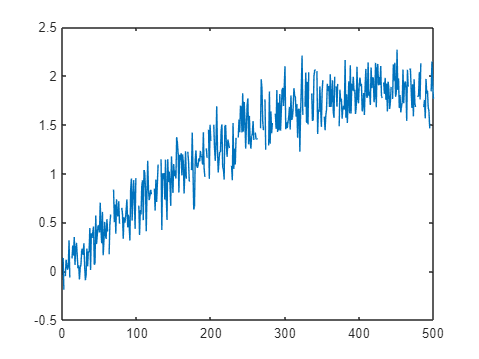

SNR=10;

signal_woNoise = sin(2*pi*frequencies(1) * t/50) + sin(2*pi*frequencies(2) * t/50);
missing_percentage = 0.1;
missing_indices = randperm(N, floor(N * missing_percentage));

% Remove the indices corresponding to missing data
signal_woNoise(missing_indices) = NaN;
signal_woNoise;

signal_power = mean(signal_woNoise.^2);
% sigma_e = sqrt(signal_power/SNR);

sigma_e= nanvar(signal_woNoise) / (10^(SNR/10));
% Add noise to the signal
e_k = sqrt(sigma_e) * randn(size(signal_woNoise));

N_new=length(signal_woNoise);
% ek = normrnd(0,sigma_e,N_new,1)';

% Plotting the signal
signal= signal_woNoise + e_k;
plot(signal)

### Training

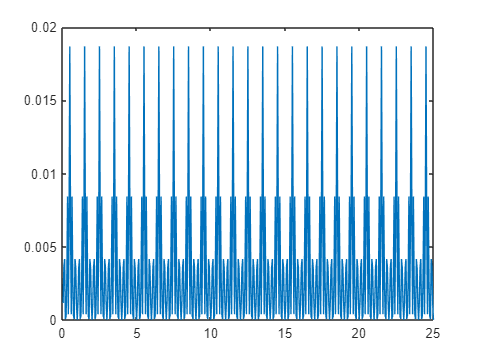

max_iterations = 10000;
learning_rate = 0.000001;
tolerance=0.01;
[a_estimated, b_estimated,y_predicted,NMSE,MAPE,periodogram] = lsp_gradient_descent(signal, frequencies_modelling, max_iterations, learning_rate,tolerance);

plot(frequencies_modelling,periodogram)

% MAPE= mean(abs((y_predicted-signal)./(signal)))*100

### **Displaying the Metrics**

disp('Estimated parameters (a_i):');

Estimated parameters (a_i):


disp(a_estimated);

    0.0159
    0.0197
   -0.0371
    0.0035
   -0.0164
   -0.0230
    0.0301
    0.0034
    0.0776
    0.0000
   -0.0360
    0.0174
    0.0746
    0.0507
    0.0013
    0.0054
    0.0611
    0.0484
    0.0244
    0.0000
    0.0159
    0.0197
   -0.0371
    0.0035
   -0.0164
   -0.0230
    0.0301
    0.0034
    0.0776
    0.0000
   -0.0360
    0.0174
    0.0746
    0.0507
    0.0013
    0.0054
    0.0611
    0.0484
    0.0244
    0.0000
    0.0159
    0.0197
   -0.0371
    0.0035
   -0.0164
   -0.0230
    0.0301
    0.0034
    0.0776
    0.0000
   -0.0360
    0.0174
    0.0746
    0.0507
    0.0013
    0.0054
    0.0611
    0.0484
    0.0244
    0.0000
    0.0159
    0.0197
   -0.0371
    0.0035
   -0.0164
   -0.0230
    0.0301
    0.0034
    0.0776
    0.0000
   -0.0360
    0.0174
    0.0746
    0.0507
    0.0013
    0.0054
    0.0611
    0.0484
    0.0244
    0.0000
    0.0159
    0.0197
   -0.0371
    0.0035
   -0.0164
   -0.0230
    0.0301
    0.0034
    0.0776
    0.0000
   -0.0360

disp('Estimated parameters (b_i):');

Estimated parameters (b_i):


disp(b_estimated);

   -0.0301
   -0.0564
   -0.0527
   -0.0067
    0.0035
   -0.0461
   -0.0868
   -0.0191
    0.0145
    0.1367
   -0.0703
   -0.0088
   -0.0536
    0.0089
    0.0167
   -0.0052
    0.0206
   -0.0350
   -0.0238
   -0.0000
   -0.0301
   -0.0564
   -0.0527
   -0.0067
    0.0035
   -0.0461
   -0.0868
   -0.0191
    0.0145
    0.1367
   -0.0703
   -0.0088
   -0.0536
    0.0089
    0.0167
   -0.0052
    0.0206
   -0.0350
   -0.0238
   -0.0000
   -0.0301
   -0.0564
   -0.0527
   -0.0067
    0.0035
   -0.0461
   -0.0868
   -0.0191
    0.0145
    0.1367
   -0.0703
   -0.0088
   -0.0536
    0.0089
    0.0167
   -0.0052
    0.0206
   -0.0350
   -0.0238
   -0.0000
   -0.0301
   -0.0564
   -0.0527
   -0.0067
    0.0035
   -0.0461
   -0.0868
   -0.0191
    0.0145
    0.1367
   -0.0703
   -0.0088
   -0.0536
    0.0089
    0.0167
   -0.0052
    0.0206
   -0.0350
   -0.0238
   -0.0000
   -0.0301
   -0.0564
   -0.0527
   -0.0067
    0.0035
   -0.0461
   -0.0868
   -0.0191
    0.0145
    0.1367
   -0.0703

% disp('The predicted signal is:')
% disp(y_predicted)
disp('NMSE')

NMSE


disp(NMSE)

    0.4551



disp('MAPE')

MAPE


disp(MAPE)

  101.0862



### Function definition

function [a_estimated, b_estimated,y_predicted, error_final,MAPE,periodogram] = lsp_gradient_descent(signal, frequencies, max_iterations, learning_rate, tol)
    
     nan_indices = isnan(signal);
     signal(nan_indices) = 0; 


    % Initialize parameters (a_i and b_i)
    num_frequencies = length(frequencies);
    a = zeros(num_frequencies, 1);
    b = zeros(num_frequencies, 1);
    
    % Mean-center the signal
    signal_mean = mean(signal);
    centered_signal = signal - signal_mean;
    N = length(signal);

    % Gradient descent
    for iter = 1:max_iterations

        gradient_a = zeros(num_frequencies, 1);
        gradient_b = zeros(num_frequencies, 1);
        cos_term_f=zeros(num_frequencies,N, 1);
        sin_term_f=zeros(num_frequencies,N, 1);

        t_k = 1:N; % Time index

        for i = 1:num_frequencies
            cos_term = cos(2 * pi * frequencies(i) * t_k);
            sin_term = sin(2 * pi * frequencies(i) * t_k);
            residual = centered_signal - a(i) * cos_term - b(i) * sin_term;
            gradient_a(i) = 2 * sum(residual .* sin_term);
            gradient_b(i) = -2 * sum(residual .* cos_term);
            cos_term_f(i,:)=cos_term;
            sin_term_f(i,:)=sin_term;
            

        end
        
        % Update parameters
        a = a - learning_rate * gradient_a;
        b = b - learning_rate * gradient_b;
    
        periodogram = (a.^2+ b.^2)';
        % Check termination condition
        if norm(gradient_a) + norm(gradient_b) < tol 
            fprintf('Termination Reached\n');
            break;
        end
    end


    a_estimated=a;
    b_estimated=b;

    y_predicted=  a .* cos_term_f + b .* sin_term_f;
    y_predicted= sum(y_predicted,1)/num_frequencies;

    y_error= (centered_signal-y_predicted).^2;
    error_final=mean(y_error);
    
    %To avoid 0/0 form

    non_zero_indices = signal ~= 0;
    signal_non_zero = signal(non_zero_indices);
    y_predicted_non_zero = y_predicted(non_zero_indices);

    % Calculate MAPE
    MAPE = mean(abs((y_predicted_non_zero - signal_non_zero) ./ signal_non_zero)) * 100;
    
    
end



The plots for the synthetic signal and the periodogram have been plotted above. The values of NMSE and MAPE have been reported for the lomb scale periodogram estimator. Signal has been reconstructed by taking the sum of the signals obatained for each (a,b) pair for the chosen modelling frequencies.